# Team 3: Hexapod Robot Leg Dynamics

#### Gary Encinas, Justin Fossum, Jason Munger, and Mithulesh Ramkumar

## Building The Model

The hexapod robot can initially be lookoed at as each leg being it's own RRR type robot which we can build the dynamic model for in two ways. The first is to build everything out by hand as taught in our Dynamics and Controls classes using the lagrangian method. The second method is to utilize the tools we have available in MATLAB with the Robotics System Toolbox.

### The Basics

We know that we want our robot to have a three revolute joints and would have a basic diagram as shown in Fig. 1.

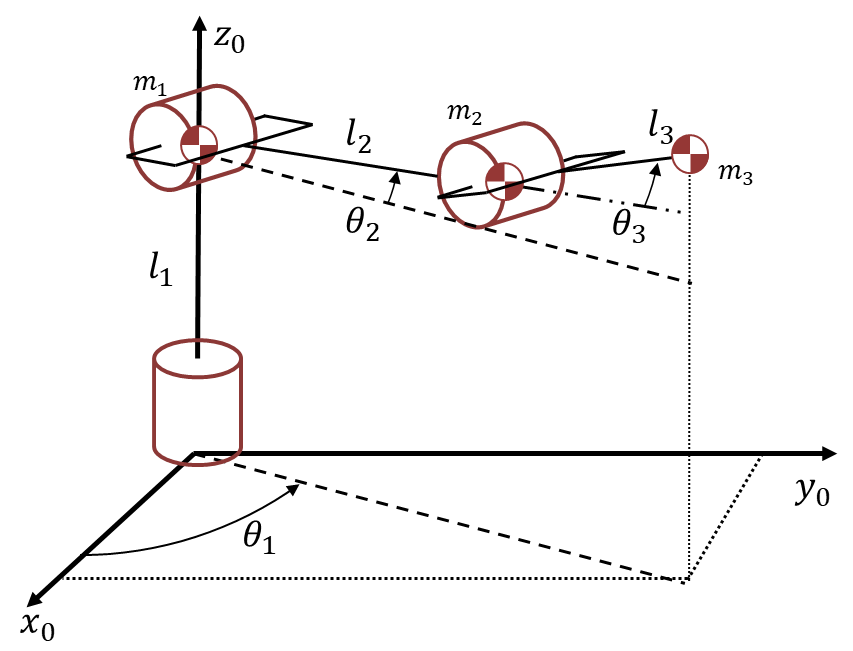

**Figure 1: RRR Robot layout model.**

From this layout we can also easily determine our Denavit-Hartenberg (DH) parameters as shown in Table 1.

**Table 1: RRR Robot DH parameters.**

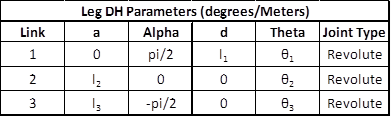

Now we can work on our models.

### Lagrangian Method Type A

This method has some simplifications in it such that it assumes the links are massless and we only have point masses at the end of the links. This is not ideal as there would be no associated rotational kinetic energy when moving, and could over estimate the torque needed by each motor as the point mass is further away than the actual Center of Mass. This model will provide us with insight and hopefully the shortcomings of this model are removed when we move the the Rigid Body Tree Model next.

First, we should remove items from workspace, freeing up system memory, and clear current command window

clear;
clc;

Now we can define our symbolic variables,

syms q1 q2 q3;
syms l1 l2 l3;
syms dq1 dq2 dq3 ddq1 ddq2 ddq3 real;
syms m1 m2 m3 g real;

and assign the DH params that define the kinematics of the RRR robot.

a = [0 l2 l3];
alpha = [pi/2 0 -pi/2];
d = [l1 0 0];
theta = [q1 q2 q3];
DHparams = [a(1)      alpha(1)      d(1)   theta(1);
            a(2)      alpha(2)      d(2)   theta(2);
            a(3)      alpha(3)      d(3)   theta(3)];

We can now get the transformation matrices defining each link with respect to the previous link

[T01] = DHparameters(DHparams(1,:));
T01 = simplify(T01)

$$T01 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & 0 & \sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & 0 & -\cos\left(q_{1}\right) & 0\\ 0 & 1 & 0 & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

[T12] = DHparameters(DHparams(2,:));
T12 = simplify(T12)

$$T12 = \left(\begin{array}{cccc} \cos\left(q_{2}\right) & -\sin\left(q_{2}\right) & 0 & l_{2}\,\cos\left(q_{2}\right)\\ \sin\left(q_{2}\right) & \cos\left(q_{2}\right) & 0 & l_{2}\,\sin\left(q_{2}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

[T23] = DHparameters(DHparams(3,:));
T23 = simplify(T23)

$$T23 = \left(\begin{array}{cccc} \cos\left(q_{3}\right) & 0 & -\sin\left(q_{3}\right) & l_{3}\,\cos\left(q_{3}\right)\\ \sin\left(q_{3}\right) & 0 & \cos\left(q_{3}\right) & l_{3}\,\sin\left(q_{3}\right)\\ 0 & -1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

and solve for each link in the base frame.

T02 = simplify(T01 * T12)

$$T02 = \left(\begin{array}{cccc} \cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & -\cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & \sin\left(q_{1}\right) & l_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\\ \cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & -\sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & -\cos\left(q_{1}\right) & l_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ \sin\left(q_{2}\right) & \cos\left(q_{2}\right) & 0 & l_{1}+l_{2}\,\sin\left(q_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T03 = simplify(T02 * T23)

$$T03 = \begin{array}{l} \left(\begin{array}{cccc} \cos\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & -\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right) & \cos\left(q_{1}\right)\,\sigma_{1}\\ \cos\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right) & -\sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sigma_{1}\\ \sin\left(q_{2}+q_{3}\right) & 0 & \cos\left(q_{2}+q_{3}\right) & l_{1}+l_{3}\,\sin\left(q_{2}+q_{3}\right)+l_{2}\,\sin\left(q_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{3}\,\cos\left(q_{2}+q_{3}\right)+l_{2}\,\cos\left(q_{2}\right) \end{array}$$

Plotting the links and joints to verify that we have the correct DH parameter asssignment. For this, $l_1$, $l_2$, and $l_3$ were given arbetrary values to show a similar layout as displayed in Fig. 1.

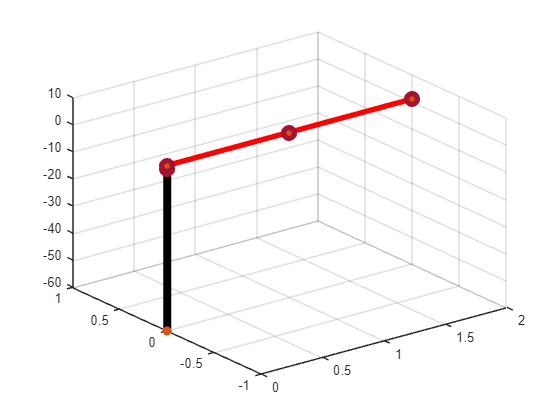

plot3([0 0],[0 0],[-60 0],'-ko','LineWidth',6,'MarkerEdgeColor','#D95319','MarkerFaceColor','g','MarkerSize',1);
grid on;
hold on;
t = [0 0 0];
T01_temp = subs(T01, [l1 l2 l3 q1 q2 q3], [1 1 1 t(1) t(2) t(3)]);
T02_temp = subs(T02, [l1 l2 l3 q1 q2 q3], [1 1 1 t(1) t(2) t(3)]);
T03_temp = subs(T03, [l1 l2 l3 q1 q2 q3], [1 1 1 t(1) t(2) t(3)]);
x = [0 T01_temp(1,4) T02_temp(1,4) T03_temp(1,4)];
y = [0 T01_temp(2,4) T02_temp(2,4) T03_temp(2,4)];
z = [0 T01_temp(3,4) T02_temp(3,4) T03_temp(3,4)];
plot3(x,y,z,'-ro','LineWidth',4,'MarkerEdgeColor','#A2142F','MarkerFaceColor','#D95319','MarkerSize',8);

To solve for the lagrangian dynamics, we need the kinetic and potential energies of all the link masses. To compute the Kinetic Energy of each link, we need the Jacobian matrix that relates the angular velocity of link  to linear velocity at the tip. We also know that each link has its mass at the end of the link. Therefore the Jacobian Matrices of link 1, 2 and 3 are

J_l1 = jacobian(T01(1:3,4),q1);
J_l2 = jacobian(T02(1:3,4),[q1 q2]);
J_l3 = jacobian(T03(1:3,4),[q1 q2 q3]);
J_l1 = simplify(J_l1)

$$J\_l1 = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

J_l2 = simplify(J_l2)

$$J\_l2 = \left(\begin{array}{cc} -l_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & -l_{2}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ l_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & -l_{2}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ 0 & l_{2}\,\cos\left(q_{2}\right) \end{array}\right)$$

J_l3 = simplify(J_l3)

$$J\_l3 = \begin{array}{l} \left(\begin{array}{ccc} -\sin\left(q_{1}\right)\,\sigma_{1} & -\cos\left(q_{1}\right)\,\sigma_{2} & -l_{3}\,\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right)\\ \cos\left(q_{1}\right)\,\sigma_{1} & -\sin\left(q_{1}\right)\,\sigma_{2} & -l_{3}\,\sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right)\\ 0 & \sigma_{1} & l_{3}\,\cos\left(q_{2}+q_{3}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{3}\,\cos\left(q_{2}+q_{3}\right)+l_{2}\,\cos\left(q_{2}\right)\\ \sigma_{2}=l_{3}\,\sin\left(q_{2}+q_{3}\right)+l_{2}\,\sin\left(q_{2}\right) \end{array}$$

Next, we can calculate the velocity at each mass with respect to the base frame. We simply multiply the Jacobian with the angular velocity of the joint.

v_m1 = J_l1 * dq1;
v_m2 = J_l2 * [dq1 ; dq2];
v_m3 = J_l3 * [dq1 ; dq2 ; dq3];
v_m1 = simplify(v_m1)

$$v\_m1 = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

v_m2 = simplify(v_m2)

$$v\_m2 = \left(\begin{array}{c} -{\mathrm{dq}}_{1}\,l_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)-{\mathrm{dq}}_{2}\,l_{2}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ {\mathrm{dq}}_{1}\,l_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-{\mathrm{dq}}_{2}\,l_{2}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ {\mathrm{dq}}_{2}\,l_{2}\,\cos\left(q_{2}\right) \end{array}\right)$$

v_m3 = simplify(v_m3)

$$v\_m3 = \begin{array}{l} \left(\begin{array}{c} -{\mathrm{dq}}_{1}\,\sin\left(q_{1}\right)\,\sigma_{1}-{\mathrm{dq}}_{2}\,\cos\left(q_{1}\right)\,\sigma_{2}-{\mathrm{dq}}_{3}\,l_{3}\,\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right)\\ {\mathrm{dq}}_{1}\,\cos\left(q_{1}\right)\,\sigma_{1}-{\mathrm{dq}}_{2}\,\sin\left(q_{1}\right)\,\sigma_{2}-{\mathrm{dq}}_{3}\,l_{3}\,\sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right)\\ {\mathrm{dq}}_{2}\,\sigma_{1}+{\mathrm{dq}}_{3}\,l_{3}\,\cos\left(q_{2}+q_{3}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{3}\,\cos\left(q_{2}+q_{3}\right)+l_{2}\,\cos\left(q_{2}\right)\\ \sigma_{2}=l_{3}\,\sin\left(q_{2}+q_{3}\right)+l_{2}\,\sin\left(q_{2}\right) \end{array}$$

Then we compute the Kinetic Energy of each mass. Since the links are defined to be massless, we do not have any associated rotational kinetic energy.

K1 = 0.5 * m1 * (v_m1.' * v_m1);
K2 = 0.5 * m2 * (v_m2.' * v_m2);
K3 = 0.5 * m3 * (v_m3.' * v_m3);
K1 = simplify(K1)

$$K1 = 0$$

K2 = simplify(K2)

$$K2 = \frac{{l_{2}}^{2}\,m_{2}\,\left(-{{\mathrm{dq}}_{1}}^{2}\,{\sin\left(q_{2}\right)}^{2}+{{\mathrm{dq}}_{1}}^{2}+{{\mathrm{dq}}_{2}}^{2}\right)}{2}$$

K3 = simplify(K3)

$$K3 = \frac{m_{3}\,\left(\frac{{{\mathrm{dq}}_{1}}^{2}\,{l_{2}}^{2}}{2}+\frac{{{\mathrm{dq}}_{1}}^{2}\,{l_{3}}^{2}}{2}+{{\mathrm{dq}}_{2}}^{2}\,{l_{2}}^{2}+{{\mathrm{dq}}_{2}}^{2}\,{l_{3}}^{2}+{{\mathrm{dq}}_{3}}^{2}\,{l_{3}}^{2}+\frac{{{\mathrm{dq}}_{1}}^{2}\,{l_{2}}^{2}\,\cos\left(2\,q_{2}\right)}{2}+\frac{{{\mathrm{dq}}_{1}}^{2}\,{l_{3}}^{2}\,\cos\left(2\,q_{2}+2\,q_{3}\right)}{2}+2\,{\mathrm{dq}}_{2}\,{\mathrm{dq}}_{3}\,{l_{3}}^{2}+{{\mathrm{dq}}_{1}}^{2}\,l_{2}\,l_{3}\,\cos\left(q_{3}\right)+2\,{{\mathrm{dq}}_{2}}^{2}\,l_{2}\,l_{3}\,\cos\left(q_{3}\right)+{{\mathrm{dq}}_{1}}^{2}\,l_{2}\,l_{3}\,\cos\left(2\,q_{2}+q_{3}\right)+2\,{\mathrm{dq}}_{2}\,{\mathrm{dq}}_{3}\,l_{2}\,l_{3}\,\cos\left(q_{3}\right)\right)}{2}$$

We also need the potential energy of each mass. We use the following formula

g = 9.8;
P1 = m1 * g * T01(3,4);
P2 = m2 * g * T02(3,4);
P3 = m3 * g * T03(3,4);
P1 = simplify(P1)

$$P1 = \frac{49\,l_{1}\,m_{1}}{5}$$

P2 = simplify(P2)

$$P2 = \frac{49\,m_{2}\,\left(l_{1}+l_{2}\,\sin\left(q_{2}\right)\right)}{5}$$

P3 = simplify(P3)

$$P3 = \frac{49\,m_{3}\,\left(l_{1}+l_{3}\,\sin\left(q_{2}+q_{3}\right)+l_{2}\,\sin\left(q_{2}\right)\right)}{5}$$

Summing up all the Kinetic energies and Potential energies

K = K1 + K2 + K3

$$K = \frac{m_{3}\,\left(\frac{{{\mathrm{dq}}_{1}}^{2}\,{l_{2}}^{2}}{2}+\frac{{{\mathrm{dq}}_{1}}^{2}\,{l_{3}}^{2}}{2}+{{\mathrm{dq}}_{2}}^{2}\,{l_{2}}^{2}+{{\mathrm{dq}}_{2}}^{2}\,{l_{3}}^{2}+{{\mathrm{dq}}_{3}}^{2}\,{l_{3}}^{2}+\frac{{{\mathrm{dq}}_{1}}^{2}\,{l_{2}}^{2}\,\cos\left(2\,q_{2}\right)}{2}+\frac{{{\mathrm{dq}}_{1}}^{2}\,{l_{3}}^{2}\,\cos\left(2\,q_{2}+2\,q_{3}\right)}{2}+2\,{\mathrm{dq}}_{2}\,{\mathrm{dq}}_{3}\,{l_{3}}^{2}+{{\mathrm{dq}}_{1}}^{2}\,l_{2}\,l_{3}\,\cos\left(q_{3}\right)+2\,{{\mathrm{dq}}_{2}}^{2}\,l_{2}\,l_{3}\,\cos\left(q_{3}\right)+{{\mathrm{dq}}_{1}}^{2}\,l_{2}\,l_{3}\,\cos\left(2\,q_{2}+q_{3}\right)+2\,{\mathrm{dq}}_{2}\,{\mathrm{dq}}_{3}\,l_{2}\,l_{3}\,\cos\left(q_{3}\right)\right)}{2}+\frac{{l_{2}}^{2}\,m_{2}\,\left(-{{\mathrm{dq}}_{1}}^{2}\,{\sin\left(q_{2}\right)}^{2}+{{\mathrm{dq}}_{1}}^{2}+{{\mathrm{dq}}_{2}}^{2}\right)}{2}$$

P = P1 + P2 + P3

$$P = \frac{49\,l_{1}\,m_{1}}{5}+\frac{49\,m_{2}\,\left(l_{1}+l_{2}\,\sin\left(q_{2}\right)\right)}{5}+\frac{49\,m_{3}\,\left(l_{1}+l_{3}\,\sin\left(q_{2}+q_{3}\right)+l_{2}\,\sin\left(q_{2}\right)\right)}{5}$$

Computing the lagrangian

L = simplify( K - P )

$$L = \frac{{{\mathrm{dq}}_{1}}^{2}\,{l_{2}}^{2}\,m_{2}}{4}-\frac{49\,l_{1}\,m_{2}}{5}-\frac{49\,l_{1}\,m_{3}}{5}-\frac{49\,l_{2}\,m_{2}\,\sin\left(q_{2}\right)}{5}-\frac{49\,l_{2}\,m_{3}\,\sin\left(q_{2}\right)}{5}-\frac{49\,l_{1}\,m_{1}}{5}+\frac{{{\mathrm{dq}}_{1}}^{2}\,{l_{2}}^{2}\,m_{3}}{4}+\frac{{{\mathrm{dq}}_{2}}^{2}\,{l_{2}}^{2}\,m_{2}}{2}+\frac{{{\mathrm{dq}}_{1}}^{2}\,{l_{3}}^{2}\,m_{3}}{4}+\frac{{{\mathrm{dq}}_{2}}^{2}\,{l_{2}}^{2}\,m_{3}}{2}+\frac{{{\mathrm{dq}}_{2}}^{2}\,{l_{3}}^{2}\,m_{3}}{2}+\frac{{{\mathrm{dq}}_{3}}^{2}\,{l_{3}}^{2}\,m_{3}}{2}-\frac{49\,l_{3}\,m_{3}\,\sin\left(q_{2}+q_{3}\right)}{5}+{\mathrm{dq}}_{2}\,{\mathrm{dq}}_{3}\,{l_{3}}^{2}\,m_{3}+\frac{{{\mathrm{dq}}_{1}}^{2}\,{l_{2}}^{2}\,m_{2}\,\cos\left(2\,q_{2}\right)}{4}+\frac{{{\mathrm{dq}}_{1}}^{2}\,{l_{2}}^{2}\,m_{3}\,\cos\left(2\,q_{2}\right)}{4}+\frac{{{\mathrm{dq}}_{1}}^{2}\,{l_{3}}^{2}\,m_{3}\,\cos\left(2\,q_{2}+2\,q_{3}\right)}{4}+\frac{{{\mathrm{dq}}_{1}}^{2}\,l_{2}\,l_{3}\,m_{3}\,\cos\left(q_{3}\right)}{2}+{{\mathrm{dq}}_{2}}^{2}\,l_{2}\,l_{3}\,m_{3}\,\cos\left(q_{3}\right)+\frac{{{\mathrm{dq}}_{1}}^{2}\,l_{2}\,l_{3}\,m_{3}\,\cos\left(2\,q_{2}+q_{3}\right)}{2}+{\mathrm{dq}}_{2}\,{\mathrm{dq}}_{3}\,l_{2}\,l_{3}\,m_{3}\,\cos\left(q_{3}\right)$$

This is the equation for the Euler Lagrange Dynamics $\tau_i =\frac{d}{\mathrm{dt}}\frac{\delta L}{\delta \dot{q_i } }-\frac{\delta L}{\delta d_i }$ where $i\in \left(1,2,3\right)$

Treating $\tau_i =\frac{d}{\mathrm{dt}}\frac{\delta L}{\delta \dot{q_i } }-\frac{\delta L}{\delta d_i }$ as $\tau_i =\frac{d}{\mathrm{dt}}A-B$

syms th1(t) th2(t) th3(t);

First differentiate A1 with respect to $\theta_i$

A1 = diff(L,dq1);

The replace variables of q1, q2, q3 and their derivatives with the time-dependant counter parts. This is done so that we can differentiate with respect to time in the next step.

A1t = subs(A1,[q1 q2 q3 dq1 dq2 dq3], [th1 th2 th3 diff(th1(t),t) diff(th2(t),t) diff(th3(t),t)]);

Differentiate with respect to time

dA1t = diff(A1t, t);

Replace the time-dependant varialbes with non-time dependant varialbes to make the output look cleaner

A1 = subs(dA1t,[th1, th2, th3, diff(th1(t),t), diff(th2(t),t), diff(th3(t),t), diff(th1(t),t,t), diff(th2(t),t,t), diff(th3(t),t,t)],[q1, q2, q3, dq1, dq2, dq3, ddq1, ddq2, ddq3]);

Compute B1 for first link

B1 = diff(L,q1);

Repeat for all the links

A2 = diff(L,dq2);
A2t = subs(A2,[q1 q2 q3 dq1 dq2 dq3], [th1 th2 th3 diff(th1(t),t) diff(th2(t),t) diff(th3(t),t)]);
dA2t = diff(A2t, t);
A2 = dA2t %subs(dA2t,[th1 th2 th3 diff(th1(t),t) diff(th2(t),t) diff(th3(t),t) diff(th1(t),t,t) diff(th2(t),t,t) diff(th3(t),t,t)],[q1 q2 q3 dq1 dq2 dq3 ddq1 ddq2 ddq3]);

$$A2 = \begin{array}{l} {l_{2}}^{2}\,m_{2}\,\sigma_{1}+{l_{2}}^{2}\,m_{3}\,\sigma_{1}+{l_{3}}^{2}\,m_{3}\,\sigma_{1}+{l_{3}}^{2}\,m_{3}\,\sigma_{2}-l_{2}\,l_{3}\,m_{3}\,\sin\left({\mathrm{th}}_{3}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}{\mathrm{th}}_{3}\left(t\right)\right)}^{2}+2\,l_{2}\,l_{3}\,m_{3}\,\cos\left({\mathrm{th}}_{3}\left(t\right)\right)\,\sigma_{1}+l_{2}\,l_{3}\,m_{3}\,\cos\left({\mathrm{th}}_{3}\left(t\right)\right)\,\sigma_{2}-2\,l_{2}\,l_{3}\,m_{3}\,\sin\left({\mathrm{th}}_{3}\left(t\right)\right)\,\frac{\partial }{\partial t}{\mathrm{th}}_{3}\left(t\right)\,\frac{\partial }{\partial t}{\mathrm{th}}_{2}\left(t\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial^{2}}{\partial t^{2}}{\mathrm{th}}_{2}\left(t\right)\\ \sigma_{2}=\frac{\partial^{2}}{\partial t^{2}}{\mathrm{th}}_{3}\left(t\right) \end{array}$$

B2 = diff(L,q2);

A3 = diff(L,dq3);
A3t = subs(A3,[q1 q2 q3 dq1 dq2 dq3], [th1 th2 th3 diff(th1(t),t) diff(th2(t),t) diff(th3(t),t)]);
dA3t = diff(A3t, t);
A3 = dA3t %subs(dA3t,[th1 th2 th3 diff(th1(t),t) diff(th2(t),t) diff(th3(t),t) diff(th1(t),t,t) diff(th2(t),t,t) diff(th3(t),t,t)],[q1 q2 q3 dq1 dq2 dq3 ddq1 ddq2 ddq3]);

$$A3 = {l_{3}}^{2}\,m_{3}\,\frac{\partial^{2}}{\partial t^{2}}{\mathrm{th}}_{2}\left(t\right)+{l_{3}}^{2}\,m_{3}\,\frac{\partial^{2}}{\partial t^{2}}{\mathrm{th}}_{3}\left(t\right)+l_{2}\,l_{3}\,m_{3}\,\cos\left({\mathrm{th}}_{3}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}{\mathrm{th}}_{2}\left(t\right)-l_{2}\,l_{3}\,m_{3}\,\sin\left({\mathrm{th}}_{3}\left(t\right)\right)\,\frac{\partial }{\partial t}{\mathrm{th}}_{3}\left(t\right)\,\frac{\partial }{\partial t}{\mathrm{th}}_{2}\left(t\right)$$

B3 = diff(L,q3);

Tau_l1 = A1 - B1;
Tau_l2 = A2 - B2;
Tau_l3 = A3 - B3;

Now we want to split the dynamics into the M, C and G matrices.

M11 = simplify(Tau_l1 - subs(Tau_l1,ddq1,0)) /ddq1;
M12 = simplify(Tau_l1 - subs(Tau_l1,ddq2,0)) /ddq2;
M13 = simplify(Tau_l1 - subs(Tau_l1,ddq3,0)) /ddq3;

M21 = simplify(Tau_l2 - subs(Tau_l2,ddq1,0)) /ddq1;
M22 = simplify(Tau_l2 - subs(Tau_l2,ddq2,0)) /ddq2;
M23 = simplify(Tau_l2 - subs(Tau_l2,ddq3,0)) /ddq3;

M31 = simplify(Tau_l3 - subs(Tau_l3,ddq1,0)) /ddq1;
M32 = simplify(Tau_l3 - subs(Tau_l3,ddq2,0)) /ddq2;
M33 = simplify(Tau_l3 - subs(Tau_l3,ddq3,0)) /ddq3;

G11 = subs(Tau_l1, [dq1 dq2 dq3 ddq1 ddq2 ddq3], [0 0 0 0 0 0]);
G21 = subs(Tau_l2, [dq1 dq2 dq3 ddq1 ddq2 ddq3], [0 0 0 0 0 0]);
G31 = subs(Tau_l3, [dq1 dq2 dq3 ddq1 ddq2 ddq3], [0 0 0 0 0 0]);

The intertia matrix is as follows

M = [M11 M12 M13;
M21 M22 M23;
M31 M32 M33];

This is the gravity vector

G = simplify([G11; G21; G31]);
C11 = Tau_l1 - (M(1,:) * [ddq1 ddq2 ddq3].' + G11);
C21 = Tau_l2 - (M(2,:) * [ddq1 ddq2 ddq3].' + G21);
C31 = Tau_l3 - (M(3,:) * [ddq1 ddq2 ddq3].' + G31);

This is the Coriolis Vector

C = simplify([C11; C21; C31]);

This is the Mass Matrix

M

$$M = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

This is the Coriolis Matrix

C

$$C = \begin{array}{l} \left(\begin{array}{c} 0\\ \frac{{{\mathrm{dq}}_{1}}^{2}\,\left({l_{3}}^{2}\,m_{3}\,\sigma_{1}+{l_{2}}^{2}\,m_{2}\,\sin\left(2\,q_{2}\right)+{l_{2}}^{2}\,m_{3}\,\sin\left(2\,q_{2}\right)+2\,l_{2}\,l_{3}\,m_{3}\,\sigma_{2}\right)}{2}\\ \frac{l_{3}\,m_{3}\,\left({{\mathrm{dq}}_{1}}^{2}\,l_{3}\,\sigma_{1}+{{\mathrm{dq}}_{1}}^{2}\,l_{2}\,\sin\left(q_{3}\right)+2\,{{\mathrm{dq}}_{2}}^{2}\,l_{2}\,\sin\left(q_{3}\right)+{{\mathrm{dq}}_{1}}^{2}\,l_{2}\,\sigma_{2}+2\,{\mathrm{dq}}_{2}\,{\mathrm{dq}}_{3}\,l_{2}\,\sin\left(q_{3}\right)\right)}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(2\,q_{2}+2\,q_{3}\right)\\ \sigma_{2}=\sin\left(2\,q_{2}+q_{3}\right) \end{array}$$

This is the Gravity Matrix

G

$$G = \begin{array}{l} \left(\begin{array}{c} 0\\ \frac{49\,l_{2}\,m_{2}\,\cos\left(q_{2}\right)}{5}+\frac{49\,l_{2}\,m_{3}\,\cos\left(q_{2}\right)}{5}+{l_{2}}^{2}\,m_{2}\,\sigma_{5}+{l_{2}}^{2}\,m_{3}\,\sigma_{5}+\sigma_{3}+\sigma_{2}+\sigma_{1}-l_{2}\,l_{3}\,m_{3}\,\sin\left({\mathrm{th}}_{3}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}{\mathrm{th}}_{3}\left(t\right)\right)}^{2}+2\,l_{2}\,l_{3}\,m_{3}\,\cos\left({\mathrm{th}}_{3}\left(t\right)\right)\,\sigma_{5}+l_{2}\,l_{3}\,m_{3}\,\cos\left({\mathrm{th}}_{3}\left(t\right)\right)\,\sigma_{4}-2\,l_{2}\,l_{3}\,m_{3}\,\sin\left({\mathrm{th}}_{3}\left(t\right)\right)\,\frac{\partial }{\partial t}{\mathrm{th}}_{3}\left(t\right)\,\frac{\partial }{\partial t}{\mathrm{th}}_{2}\left(t\right)\\ \sigma_{3}+\sigma_{2}+\sigma_{1}+l_{2}\,l_{3}\,m_{3}\,\cos\left({\mathrm{th}}_{3}\left(t\right)\right)\,\sigma_{5}-l_{2}\,l_{3}\,m_{3}\,\sin\left({\mathrm{th}}_{3}\left(t\right)\right)\,\frac{\partial }{\partial t}{\mathrm{th}}_{3}\left(t\right)\,\frac{\partial }{\partial t}{\mathrm{th}}_{2}\left(t\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{49\,l_{3}\,m_{3}\,\cos\left(q_{2}+q_{3}\right)}{5}\\ \sigma_{2}={l_{3}}^{2}\,m_{3}\,\sigma_{4}\\ \sigma_{3}={l_{3}}^{2}\,m_{3}\,\sigma_{5}\\ \sigma_{4}=\frac{\partial^{2}}{\partial t^{2}}{\mathrm{th}}_{3}\left(t\right)\\ \sigma_{5}=\frac{\partial^{2}}{\partial t^{2}}{\mathrm{th}}_{2}\left(t\right) \end{array}$$

### Rigid Body Tree Model

a_rbt = [0 0.695 0.905];
alpha_rbt = [pi/2 0 -pi/2];
d_rbt = [0 0 0];
theta_rbt = [0 0 0];
DHparams_rbt = [a_rbt(1)      alpha_rbt(1)      d_rbt(1)   theta_rbt(1);
                a_rbt(2)      alpha_rbt(2)      d_rbt(2)   theta_rbt(2);
                a_rbt(3)      alpha_rbt(3)      d_rbt(3)   theta_rbt(3)];

Building The Robot by creating a rigid body tree

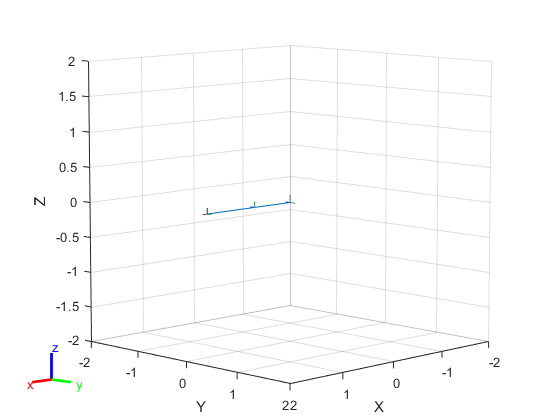

leg = robotics.RigidBodyTree; %Sets rigid body tree to be called robot for callback use

% Define the bodies and their joints
body1 = robotics.RigidBody('Link_1'); %Create Link 1 of the robot.
jnt1 = robotics.Joint('jnt1','revolute'); %Create a revolute joint.
body2 = robotics.RigidBody('Link_2'); %Create Link 2 of the robot.
jnt2 = robotics.Joint('jnt2','revolute'); %Create a revolute joint.
body3 = robotics.RigidBody('Link_3'); %Create Link 3 of the robot.
jnt3 = robotics.Joint('jnt3','revolute'); %Create a revolute joint.

% Specify the body-to-body transformation using DH parameters
setFixedTransform(jnt1,DHparams_rbt(1,:),'dh');
setFixedTransform(jnt2,DHparams_rbt(2,:),'dh');
setFixedTransform(jnt3,DHparams_rbt(3,:),'dh');

body1.Joint = jnt1;
body2.Joint = jnt2;
body3.Joint = jnt3;

body1.Mass = 29.1735;
body2.Mass = 40.0393;
body3.Mass = 22.3124;

body1.CenterOfMass = [-0.00011,-0.00606,-0.02426];
body2.CenterOfMass = [0.460299,0.01302,0.028736];
body3.CenterOfMass = [0.136857,-0.00386,0.004163];

% Attach the Bodies
addBody(leg,body1,'base')
addBody(leg,body2,'Link_1');
addBody(leg,body3,'Link_2');

figure;
show(leg);

leg.DataFormat = 'row';
leg.Gravity = [0 0 -9.81];
q = homeConfiguration(leg);
tau = inverseDynamics(leg,q)

tau =     0.0000  833.9561  228.0465


## Appendix

### DHparameters Function

This function calculates the rotation matrices based on a provided DHparameters table. By using a single row of a DH parameters table as the input you can generate the transformation matrix foran individual link. Each link's transformation matrix multiplied together would provide the same result as using the entire DH parameters table in this function.

DHparams = array of DH parameters in this format:


$$\mathrm{DH}=\left\lbrack a\;\alpha \;d\;\theta \right\rbrack$$


function [T] = DHparameters(DHparams)
% Initializations
A_old = [1 0 0 0; 0 1 0 0; 0 0 1 0; 0 0 0 1]; % Identity matrix for first iteration
rotation_count = length(DHparams(:,1));
for i = 1:rotation_count

    A_new = [cos(DHparams(i,4)) -sin(DHparams(i,4))*cos(DHparams(i,2))...
        sin(DHparams(i,4))*sin(DHparams(i,2)) DHparams(i,1)*cos(DHparams(i,4));...
        sin(DHparams(i,4)) cos(DHparams(i,4))*cos(DHparams(i,2))...
        -cos(DHparams(i,4))*sin(DHparams(i,2)) DHparams(i,1)*sin(DHparams(i,4));...
        0 sin(DHparams(i,2)) cos(DHparams(i,2)) DHparams(i,3);...
        0 0 0 1];

    A_old = A_old*A_new;
end
T = A_old;
end